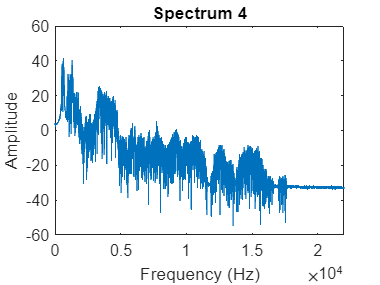

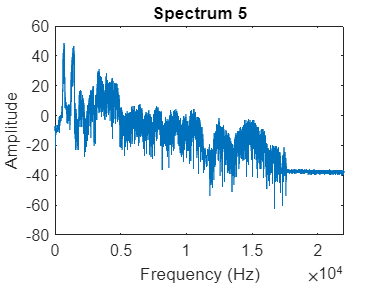

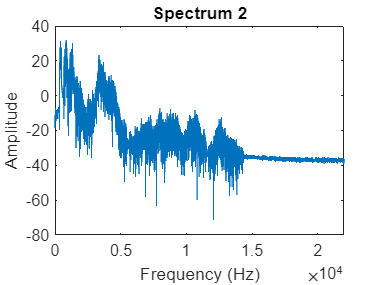

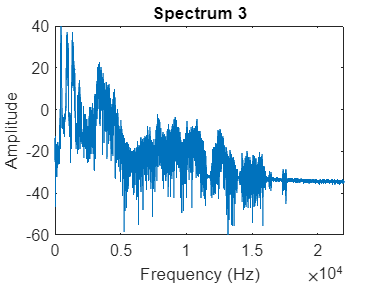

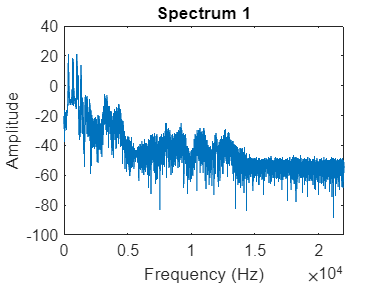

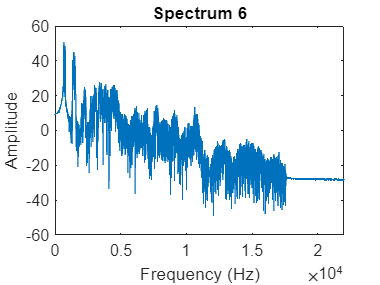

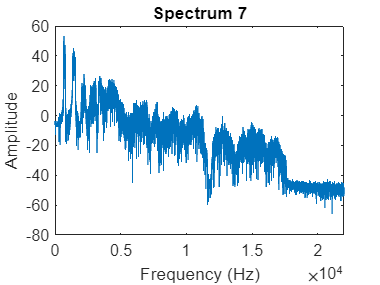

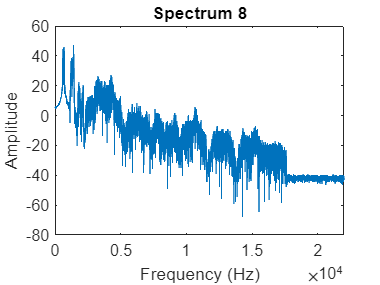

% Load the audio file
[audio_data, sample_rate] = audioread('Opera.wav');
num_spectrum = 10;
% Create and compare spectra for each window
for i = 1:num_spectrum
    start_idx = (i - 1) * 22000 + 1;
    end_idx = start_idx + 22000 - 1;
    
    % Extract the window of audio data
    spectrum_ = audio_data(start_idx:end_idx);
    
    % Compute the spectrum using the FFT
    spectrum = 20*log10(abs(fft(spectrum_)));

    
    % Calculate the corresponding frequency axis
    frequency_axis = linspace(0, sample_rate / 2, 20000 / 2 + 1);
    
    
    
    % Plot the spectrum for this window
    figure;
    plot(frequency_axis, spectrum(1:length(frequency_axis)));
    title(sprintf('Spectrum %d', i));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Adjust the x-axis limits for a better view
    xlim([0, 22000]);  % Adjust the range as needed
end

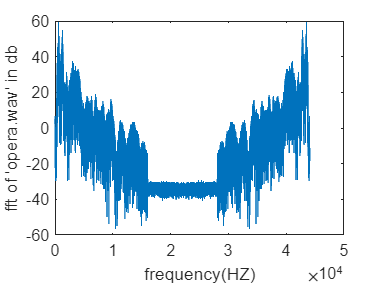

 figure
 numSamples = length(fft(audio_data));
 freqs = (0:numSamples-1) * (sample_rate / numSamples);
 
 plot(freqs,20*log10(abs(fft(audio_data))))


xlabel("frequency(HZ)")
ylabel("fft of 'opera.wav' in db")

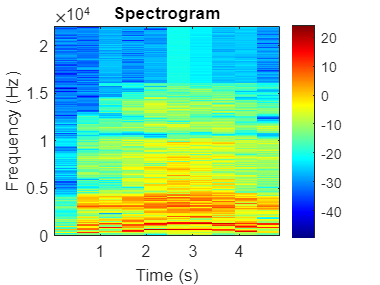

 % Example: Load an audio file
[y, Fs] = audioread('Opera.wav');
window_length = 22000;  % Window size in samples
overlap = 512;         % Overlap between consecutive windows in samples
nfft = 22000;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram');
colorbar;  % Add a colorbar to show magnitude values

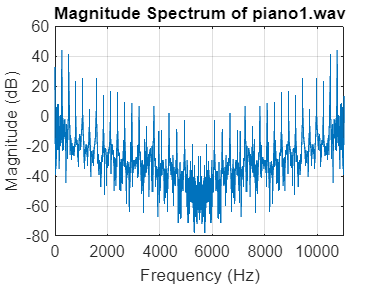

Fundamental Frequency for piano1.wav: 261.64 Hz


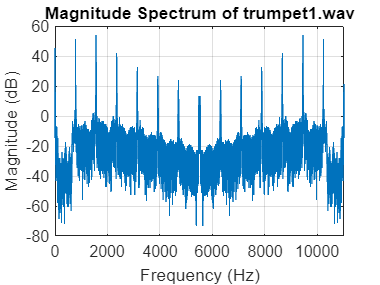

Fundamental Frequency for trumpet1.wav: 1566.24 Hz


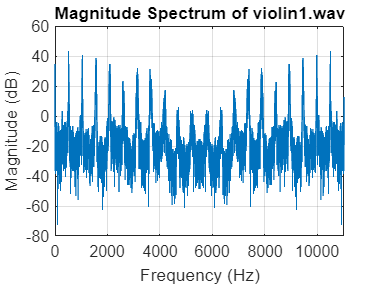

Fundamental Frequency for violin1.wav: 522.64 Hz


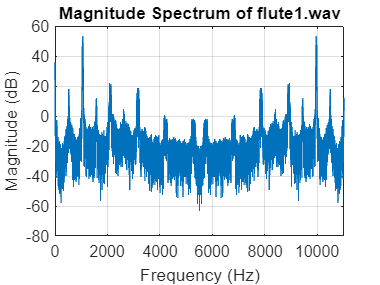

Fundamental Frequency for flute1.wav: 1063.20 Hz


fileNames = {'piano1.wav', 'trumpet1.wav', 'violin1.wav', 'flute1.wav'};


fundamentalFrequencies = zeros(1, numel(fileNames));


for i = 1:numel(fileNames)
   
    [audioData, sampleRate] = audioread(fileNames{i});

    
    fftResult = fft(audioData);
    numSamples = length(fftResult);
    freqs = (0:numSamples-1) * (sampleRate / numSamples);

    
    magnitudeSpectrumdB = 20 * log10(abs(fftResult));

    
    [~, peakIndex] = max(magnitudeSpectrumdB);

    
    fundamentalFrequency = freqs(peakIndex);

    
    fundamentalFrequencies(i) = fundamentalFrequency;

   
    figure;
    plot(freqs, magnitudeSpectrumdB);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(['Magnitude Spectrum of ' fileNames{i}]);
    grid on;
    
    
    fprintf('Fundamental Frequency for %s: %.2f Hz\n', fileNames{i}, fundamentalFrequency);
end



instrumentNames = {'Piano1', 'Trumpet1', 'Violin1', 'Flute1'};
T = table(instrumentNames', fundamentalFrequencies', 'VariableNames', {'Instrument', 'FundamentalFrequency_Hz'});
disp(T);

     Instrument     FundamentalFrequency_Hz
    ____________    _______________________

    {'Piano1'  }            261.64         
    {'Trumpet1'}            1566.2         
    {'Violin1' }            522.64         
    {'Flute1'  }            1063.2         



fileNames = {'flute2.wav','flute3.wav','flute4.wav','piano2.wav','piano3.wav','piano4.wav'};


fundamentalFrequencies = zeros(1, numel(fileNames));
for i = 1:numel(fileNames)
   
    [audioData, sampleRate] = audioread(fileNames{i});
    
    
    fftResult = fft(audioData);
    numSamples = length(fftResult);
    freqs = (0:numSamples-1) * (sampleRate / numSamples);

    
    magnitudeSpectrumdB = 20 * log10(abs(fftResult));

    
    [~, peakIndex] = max(magnitudeSpectrumdB);

    
    fundamentalFrequency = freqs(peakIndex);

    
    fundamentalFrequencies(i) = fundamentalFrequency;
     fprintf('Fundamental Frequency for %s: %.2f Hz\n', fileNames{i}, fundamentalFrequency);
end

Fundamental Frequency for flute2.wav: 524.33 Hz
Fundamental Frequency for flute3.wav: 793.50 Hz
Fundamental Frequency for flute4.wav: 524.40 Hz
Fundamental Frequency for piano2.wav: 523.62 Hz
Fundamental Frequency for piano3.wav: 1048.38 Hz
Fundamental Frequency for piano4.wav: 784.00 Hz




instrumentNames = {'flute2','flute3','flute4','piano2','piano3','piano4'};
T = table(instrumentNames', fundamentalFrequencies', 'VariableNames', {'Instrument', 'FundamentalFrequency_Hz'});
disp(T);

    Instrument    FundamentalFrequency_Hz
    __________    _______________________

    {'flute2'}            524.33         
    {'flute3'}             793.5         
    {'flute4'}             524.4         
    {'piano2'}            523.62         
    {'piano3'}            1048.4         
    {'piano4'}               784         



[y, Fs]=audioread("sita1.wav");
fftResult = fft(y);
numSamples = length(fftResult);
freqs = (0:numSamples-1) * (sampleRate / numSamples);
magnitudeSpectrumdB = 20 * log10(abs(fftResult));
[~, peakIndex] = max(magnitudeSpectrumdB);
fundamentalFrequency_reference = freqs(peakIndex)

fundamentalFrequency_reference = 1.0e+03 *

    1.4559    1.4559


plot(freqs,magnitudeSpectrumdB)

title("FFT of reference signal")
xlabel("frequency(HZ)")
ylabel("amplitude")

fundamentalFrequencies = 1.0e+03 *

    1.5370    1.5370


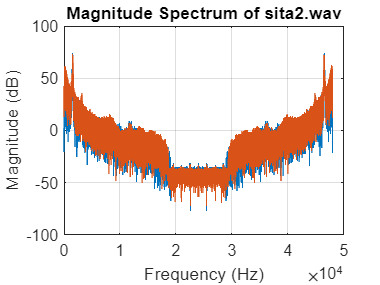

fundamentalFrequencies = 1.0e+03 *

    1.5309    1.5309


fundamentalFrequencies = 1.0e+03 *

    1.4761    1.4761


fundamentalFrequencies = 1.0e+03 *

    1.4958    1.4958


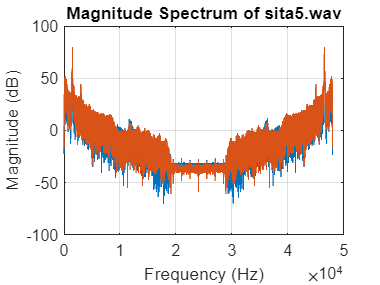

fileNames = {'sita2.wav','sita3.wav','sita4.wav','sita5.wav'};

for i = 1:numel(fileNames)
   
    [audioData, sampleRate] = audioread(fileNames{i});
    
    
    fftResult = fft(audioData);
    numSamples = length(fftResult);
    freqs = (0:numSamples-1) * (sampleRate / numSamples);

    
    magnitudeSpectrumdB = 20 * log10(abs(fftResult));

    
    [~, peakIndex] = max(magnitudeSpectrumdB);

    
    fundamentalFrequency = freqs(peakIndex);

    fundamentalFrequencies = zeros(1, numel(fileNames));
    fundamentalFrequencies = fundamentalFrequency
    
    figure;
    plot(freqs, magnitudeSpectrumdB);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(['Magnitude Spectrum of ' fileNames{i}]);
    grid on;
    
end




for i=1:numel(fundamentalFrequencies)
    if abs(fundamentalFrequencies(i) - fundamentalFrequency_reference) <= 0.05 * fundamentalFrequency_reference
        fprintf('ACCESS GRANTED\n')
    else abs(fundamentalFrequencies(i) - fundamentalFrequency_reference) >= 0.05 * fundamentalFrequency_reference
        fprintf('ACCESS DENIED\n')
    end
   
 end

ACCESS GRANTED
ACCESS GRANTED
